% Define the transfer function variable
s = tf('s');

% Given parameters
K = 0.9198;
T = 0.325;
tau = 0.089;

% Calculate the required damping ratio and natural frequency
Mp = 0.025; % 2.5% overshoot
zeta = sqrt((log(Mp))^2 / (pi^2 + (log(Mp))^2));
settling_time = 0.7; % 0.7 seconds
omega_n = 4 / (zeta * settling_time);

% Initial guess for Kp based on desired natural frequency
Kp = 0.1;

% Plant without delay
G_no_delay = K / (T * s + 1)

G_no_delay =
 
    0.9198
  -----------
  0.325 s + 1
 
Continuous-time transfer function.
Model Properties



% Plant with delay using Pade approximation
[n_pade, d_pade] = pade(tau, 1); % Pade approximation of order 1
delay_approx = tf(n_pade, d_pade)

delay_approx =
 
  -s + 22.47
  ----------
  s + 22.47
 
Continuous-time transfer function.
Model Properties



% Plant with delay approximated using Pade
G = G_no_delay * delay_approx

G =
 
       -0.9198 s + 20.67
  ---------------------------
  0.325 s^2 + 8.303 s + 22.47
 
Continuous-time transfer function.
Model Properties



% Initial P Controller
C = Kp

C = 0.1000


% Closed-loop Transfer Function
Q_s = C * G

Q_s =
 
      -0.09198 s + 2.067
  ---------------------------
  0.325 s^2 + 8.303 s + 22.47
 
Continuous-time transfer function.
Model Properties


Q_ss = 1 + Q_s

Q_ss =
 
  0.325 s^2 + 8.211 s + 24.54
  ---------------------------
  0.325 s^2 + 8.303 s + 22.47
 
Continuous-time transfer function.
Model Properties


T_s = Q_s / Q_ss

T_s =
 
      -0.02989 s^3 - 0.09198 s^2 + 15.1 s + 46.45
  ----------------------------------------------------
  0.1056 s^4 + 5.367 s^3 + 83.46 s^2 + 388.3 s + 551.4
 
Continuous-time transfer function.
Model Properties



% Analyze the step response and adjust Kp to achieve the desired specs
info = stepinfo(T_s)

info = struct with fields:
         RiseTime: 0.6448
    TransientTime: 1.2088
     SettlingTime: 1.2210
      SettlingMin: 0.0759
      SettlingMax: 0.0842
        Overshoot: 0
       Undershoot: 4.3239
             Peak: 0.0842
         PeakTime: 2.9529



% Adjust Kp until the criteria are met
while info.Overshoot > 2.5 || info.SettlingTime > 0.7
    Kp = Kp * 1.05; % Increase Kp by 5%
    C = Kp;
    Q_s = C * G;  % Recalculate Q_s with new Kp
    Q_ss = 1 + Q_s;
    
    T_s = Q_s / Q_ss; % Recalculate T_s
    info = stepinfo(T_s);
end

% Display the final value of Kp
fprintf('Final value of Kp: %.4f\n', Kp);

Final value of Kp: 0.7040


info = stepinfo(T_s);

% Display the step response characteristics
disp(info);

         RiseTime: 0.3566
    TransientTime: 0.6814
     SettlingTime: 0.6909
      SettlingMin: 0.3545
      SettlingMax: 0.3930
        Overshoot: 0
       Undershoot: 6.6282
             Peak: 0.3930
         PeakTime: 1.4784



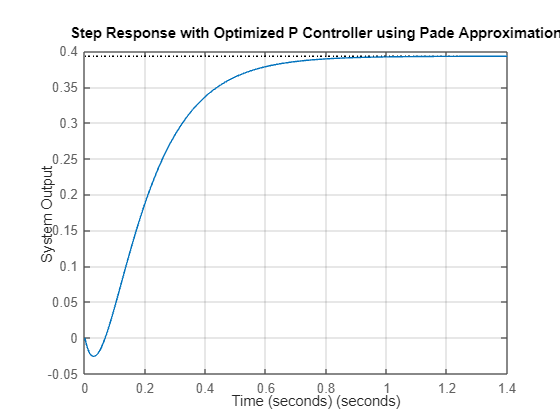


% Plot the final step response
figure;
step(T_s);
title('Step Response with Optimized P Controller using Pade Approximation');
xlabel('Time (seconds)');
ylabel('System Output');
grid on;